# Train YOLO v2 Network for Vehicle Detection

Load the training data for vehicle detection into the workspace.

data = load('vehicleTrainingData.mat');
trainingData = data.vehicleTrainingData; % Class table

Specify the directory in which training samples are stored. Add full path to the file names in training data. 

dataDir = fullfile(toolboxdir('vision'),'visiondata');
trainingData.imageFilename = fullfile(dataDir,trainingData.imageFilename);

Randomly shuffle data for training.

rng(0);
shuffledIdx = randperm(height(trainingData)); % Get table height and permute entries
trainingData = trainingData(shuffledIdx,:);

Create an imageDatastore using the files from the table.

imds = imageDatastore(trainingData.imageFilename);

Create a boxLabelDatastore using the label columns from the table.

blds = boxLabelDatastore(trainingData(:,2:end));

Combine the datastores.

ds = combine(imds, blds);

Load a preinitialized YOLO v2 object detection network.

net = load('yolov2VehicleDetector.mat');
lgraph = net.lgraph

lgraph =   LayerGraph with properties:

     InputNames: {'input'}
    OutputNames: {'yolov2OutputLayer'}
         Layers: [25×1 nnet.cnn.layer.Layer]
    Connections: [24×2 table]


Inspect the layers in the YOLO v2 network and their properties. You can also create the YOLO v2 network by following the steps given in [Create YOLO v2 Object Detection Network](docid:vision_ug#mw_4f6ea50f-8a93-4102-81a3-b2ba83bf7d58). 

lgraph.Layers

ans =   25×1 Layer array with layers:

     1   'input'               Image Input                128×128×3 images
     2   'conv_1'              2-D Convolution            16 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
     3   'BN1'                 Batch Normalization        Batch normalization
     4   'relu_1'              ReLU                       ReLU
     5   'maxpool1'            2-D Max Pooling            2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv_2'              2-D Convolution            32 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
     7   'BN2'                 Batch Normalization        Batch normalization
     8   'relu_2'              ReLU                       ReLU
     9   'maxpool2'            2-D Max Pooling            2×2 max pooling with stride [2  2] and padding [0  0  0  0]
    10   'conv_3'              2-D Convolution 

Configure the network training options.

options = trainingOptions('sgdm',...        % Set options for training the NN
          'InitialLearnRate',0.001,...
          'Verbose',true,...
          'MiniBatchSize',16,...
          'MaxEpochs',30,...
          'Shuffle','never',...
          'VerboseFrequency',30,...
          'CheckpointPath',tempdir);

Train the YOLO v2 network.

[detector,info] = trainYOLOv2ObjectDetector(ds,lgraph,options);

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* vehicle

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         7.08 |         50.1 |          0.0010 |
|       2 |          30 |       00:00:38 |         1.37 |          1.9 |          0.0010 |
|       7 |         120 |       02:47:00 |         0.53 |          0.3 |          0.0010 |
|       9 |         150 |       02:47:08 |         0.69 |          0.5 |          0.0010 |
|      15 |         270 |       22:33:27 |         0.44 |          0.2 |          0.0010 |
| 

Inspect the properties of the detector.

detector

detector =   yolov2ObjectDetector with properties:

            ModelName: 'vehicle'
              Network: [1×1 DAGNetwork]
    TrainingImageSize: [128 128]
          AnchorBoxes: [4×2 double]
           ClassNames: vehicle


You can verify the training accuracy by inspecting the training loss for each iteration.

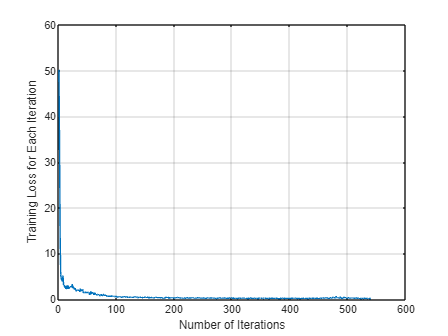

figure
plot(info.TrainingLoss)
grid on
xlabel('Number of Iterations')
ylabel('Training Loss for Each Iteration')

Read a test image into the workspace.

img = imread('detectcars.png');

Run the trained YOLO v2 object detector on the test image for vehicle detection.

[bboxes,scores] = detect(detector,img);

Display the detection results.

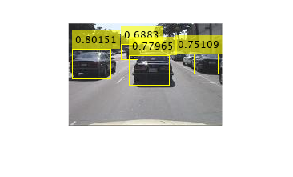

if(~isempty(bboxes))
    img = insertObjectAnnotation(img,'rectangle',bboxes,scores);
end
figure
imshow(img)

*Copyright 2018 The MathWorks, Inc.*